# Example configuration

The domain of this first example has a rectangular shape with dimensions 2500 x 1250 m. To minimized the influence of the boundary conditions, while the model is still able to converge we specify constant head boundary conditions on just two nodes of the left side which are highlighted with a green circle.

## Grid parameters

leftLower = [0, 0];
upperRight = [2500, 1250];
dx = 156.2500;
Nrows = (upperRight(2) - leftLower(2))/dx;
Ncols = (upperRight(1) - leftLower(1))/dx;

Create a finite element mesh that consists only from quadrilaterals

Meshpoly = [];
Xgrid = leftLower(1):dx:upperRight(1);
Ygrid = leftLower(2):dx:upperRight(2);
cnt = 1;
for r = 1:Nrows
    for c = 1:Ncols
        elem = [...
            Xgrid(c) Ygrid(r); ...
            Xgrid(c+1) Ygrid(r); ...
            Xgrid(c+1) Ygrid(r+1); ...
            Xgrid(c) Ygrid(r+1)
            ];
        %plot(elem(:,1), elem(:,2))
        %hold on
        Meshpoly(cnt,1).poly = elem;
        cnt = cnt + 1;
    end
end

To describe the mesh element using IWFM structure we need a unique list of node coordinates and the indices of the mesh elements that correspond to the node list

% This function is local to this script only and cannot be run at command
% window
[XY, MSH, RG] = IdentifyNodesandIndices(Meshpoly); 

Plot the finite element mesh

This snippet identifies also the stream node ids (e.g IGW for the IRV)

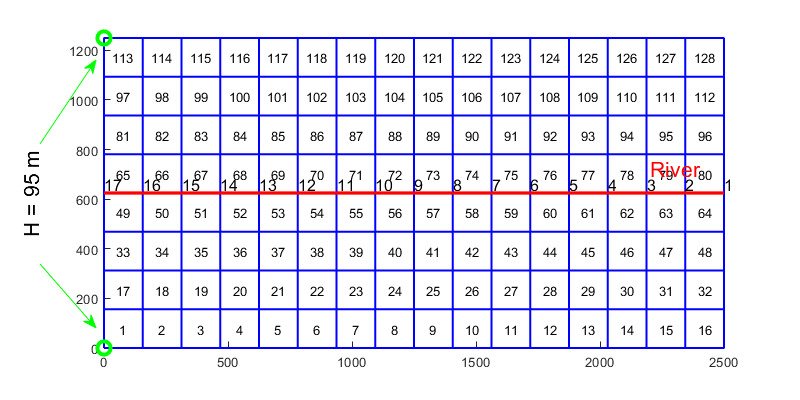

clf
set(gcf,'position',[0,0,800,400]);
hold on
for ii = 1:length(Meshpoly)
    plot(Meshpoly(ii,1).poly([1:4 1],1), Meshpoly(ii,1).poly([1:4 1],2),'b','linewidth',1.5)
    cc = mean(Meshpoly(ii,1).poly);
    text(cc(1), cc(2), num2str(ii),'HorizontalAlignment',"center",'VerticalAlignment',"middle")
end
plot([leftLower(1) upperRight(1)], [625 625],'r','linewidth',2.5) 
plot(0,0,'og','MarkerSize',10,'LineWidth',3)
plot(0,1250,'og','MarkerSize',10,'LineWidth',3)
axis equal
xlim([leftLower(1) upperRight(1)]);
ylim([leftLower(2) upperRight(2)]); 
text(leftLower(1) - 300, (leftLower(2)+upperRight(2))/2,'H = 95 m','HorizontalAlignment','center','fontsize', 16,'Rotation',90)
annotation('arrow', [0.05 0.12],[0.64 0.85],'Color','g');
annotation('arrow', [0.05 0.12],[0.34 0.18],'Color','g');
text(2200,625+100,'River','color','r','fontsize', 16)
id_stream = find(XY(:,2) == 625);
[~, ind_sort] = sort(XY(id_stream,1),'descend');
for ii = 1:length(id_stream)
    text(XY(id_stream(ind_sort(ii)),1), 660, num2str(ii),'FontSize',12)
end

Print the Nodes and element files. 

This is going to overwrite the input files and then IWFM headers would have to be inserted again. Althouth the code can run even without them for the majority of files

OverwriteFiles = false;
if OverwriteFiles
    fid = fopen(fullfile('Preprocessor', 'Ex1_Nodes.dat'),'w');
    fprintf(fid, '%d\t /ND\n',size(XY,1));
    fprintf(fid, '%.4f\t /FACT\n',1);
    fprintf(fid, '%d\t %.2f\t %.2f\n', [[1:size(XY,1)]' XY]');
    fclose(fid);
    
    fid = fopen(fullfile('Preprocessor', 'Ex1_Elements.dat'),'w');
    fprintf(fid, '%d\t /NE\n',size(MSH,1));
    fprintf(fid, '%d\t /NREGN\n',length(unique(RG)));
    for ii = 1:length(unique(RG))
       fprintf(fid, 'Subregion %d\t /RNAME%d\n', [ii ii]); 
    end
    fprintf(fid, '%d\t %d\t %d\t %d\t %d\t %d\t\n', [[1:size(MSH,1)]' MSH RG]');
    fclose(fid);
end

## Stratigraphy parameters

GSE = [101 106]; %Ground Surface Elevation (left - right)
BE = [50 50]; %Bottom elevation
Nlayers = 1;
ELEV = zeros(size(XY,1),Nlayers+1);
ELEV(:,1) = GSE(1) + (GSE(2) - GSE(1))*(XY(:,1) - leftLower(1))/(upperRight(1) - leftLower(1));
ELEV(:,Nlayers+1) = BE(1) + (BE(2) - BE(1))*(XY(:,1) - leftLower(1))/(upperRight(1) - leftLower(1));
% If there are more layers then configure their location by setting the
% following parametric value
u = [0 1];
Thickness = -diff(ELEV,1,2);
WTE = [95 101]; % Water table elevation
SBE = [91 97]; % Stream Bottom Elevation 

Plot the stratigraphy

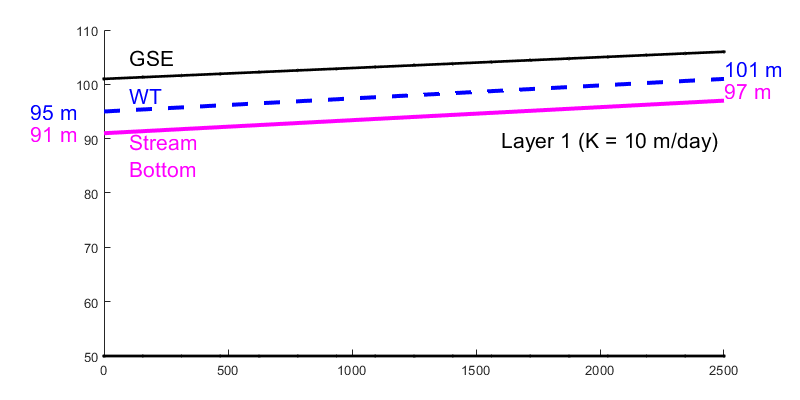

clf
set(gcf,'position',[0,0,800,400]);
hold on
for ii = 1:Nlayers+1
    plot3(XY(:,1),XY(:,2),ELEV(:,ii),'.-k','linewidth',2)
end
plot3([leftLower(1) upperRight(1)],[0 0],[WTE(1) WTE(2)],'--b','linewidth',3)
plot3([leftLower(1) upperRight(1)],[0 0],[SBE(1) SBE(2)],'-m','linewidth',3)
view(0,0)
text(1600,0,90,'Layer 1 (K = 10 m/day)','fontsize', 16)
text(100,0,105,'GSE','fontsize', 16)
text(100,0,98,'WT','fontsize', 16,'color','b')
text(100,0,87,{'Stream','Bottom'},'fontsize', 16,'color','m')
text(-300,0,91,[num2str(SBE(1)) ' m'],'fontsize', 16,'color','m')
text(-300,0,95,'95 m','fontsize', 16,'color','b')
text(2500,0,99,[num2str(SBE(2)) ' m'],'fontsize', 16,'color','m')
text(2500,0,103,'101 m','fontsize', 16,'color','b')
hold on

Print stratigraphy file

OverwriteFiles = false;
if OverwriteFiles
    fid = fopen(fullfile('Preprocessor', 'Ex1_Stratigraphy.dat'),'w');
    fprintf(fid, '%d\t /NL\n',Nlayers);
    fprintf(fid, '%.1f\t /FACT\n',1);
    fprintf(fid, '%d\t %.2f\t 0.0 %.2f\n', [(1:size(XY,1))' ELEV(:,1) Thickness]');
    fclose(fid);
end

## Stream parameters

Define a rating table

rt = [0 0 0;...
    2 734.94 10;...
    5 3299.29 15;...
    15 19033.6 36;...
    25 41568.45 2000];

Sort stream nodes according the X coordinate and calculate their bottom elevation

[B, ind_sort] = sort(XY(id_stream,1),'descend');
Stream_bot = SBE(1) + (SBE(2) - SBE(1)).*(XY(id_stream(ind_sort),1) - leftLower(1))./(upperRight(1) - leftLower(1));

Print the stream specification file.

This prints an intermediate file with suffix *.tmp. I used this to copy paste the changes to the actuall file

OverwriteFiles = false;
if OverwriteFiles
    fid = fopen(fullfile('Preprocessor', 'Ex1_StreamSpec.dat.tmp'),'w');
    fprintf(fid, '#4.1\n');
    fprintf(fid, '%d\t /NRH\n',1);
    fprintf(fid, '%d\t /NRTB\n',size(rt,1));
    fprintf(fid, '%d %d 0 REACH1\n', [1 length(id_stream)]);
    fprintf(fid, '%d %d\n', [[1:length(id_stream)]' id_stream(ind_sort)]');
    fprintf(fid, '%.1f\t /FACTLT\n',1);
    fprintf(fid, '%.1f\t /FACTQ\n',60);
    fprintf(fid, '1min\t /TUNIT\n');
    for ii = 1:length(id_stream)
        fprintf(fid, '%d\t%.2f\t %.1f %.2f\t %.1f\n',[ii Stream_bot(ii) rt(1,:)]);
        fprintf(fid, '\t\t%.1f\t%.2f\t %.1f\n', rt(2:end,:)');
    end
    fprintf(fid, '%d\t /NSTRPINT\n',0);
    fclose(fid);
end

## Local functions

function [XY, MSH, RG] = IdentifyNodesandIndices(Meshpoly)
    MSH = [];
    XY = [];
    RG = [];
    for ii = 1:size(Meshpoly,1)
        el = [];
        for jj = 1:size(Meshpoly(ii,1).poly,1)
            if isempty(XY)
                XY = Meshpoly(ii,1).poly(jj,:);
                id = 1;
            else
                xy = Meshpoly(ii,1).poly(jj,:);
                dst = sqrt((XY(:,1) - xy(1)).^2 + (XY(:,2) - xy(2)).^2);
                [cc, dd] = min(dst);
                if cc < 0.1
                    id = dd; 
                else
                    XY = [XY;xy];
                    id = length(XY);
                end
            end
            el = [el id];
        end
        cc = mean(Meshpoly(ii,1).poly);
        if cc(1) > 1250
            RG = [RG;2];
        else
            RG = [RG;1];
        end
        MSH = [MSH;el];
    end
end